# Comparison between data from a college campus and a WWTP 

Evaluation of the correlations of the viral loads found at Campus Monterrey and the Dulces Nombres WWTP, both located in the Monterrey Metropolitan Area, and clinical reports of new COVID-19 cases in the state of Nuevo Leon.

## Data import

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Week", "Tot_samples", "Coverage", "AVG_Copies", "Max_Copies", "Pos_Samples", "x_Pos_Samples", "x_Pos_Buildings", "WWTP_Copies_L", "AVG_Mob", "CasesNL"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Datos_MTY = readtable("/MATLAB Drive/Analisis de datos MARTEC/Datos_MTY.csv", opts)

Datos_MTY = 78x11 table
    Week    Tot_samples    Coverage    AVG_Copies    Max_Copies    Pos_Samples    x_Pos_Samples    x_Pos_Buildings    WWTP_Copies_L    AVG_Mob    CasesNL
    ____    ___________    ________    __________    __________    ___________    _____________    _______________    _____________    _______    _______

      1          0                0           0               0         0                 0                  0                NaN          NaN     355.5 
      2          0                0           0               0         0                 0                  0                NaN          

clear opts

## Separation of wastewater surveillance records from Campus Monterrey (WBEC) and Dulces Nombres (WWTP)

WBEC=Datos_MTY(Datos_MTY.Tot_samples>0,["Week","AVG_Copies","Max_Copies","CasesNL"]);
WWTP=Datos_MTY(:,["Week","WWTP_Copies_L","CasesNL"]);
WWTP(isnan(WWTP.WWTP_Copies_L),:)=[];

## Correlation between both data sets and clinical incidence reports 

[cWBEC,pWBEC]=corrcoef(WBEC.Max_Copies,WBEC.CasesNL);
CorrWBEC=[cWBEC(2,1) pWBEC(2,1)]

CorrWBEC =     0.4859    0.0001


Note1_WBEC="Campus MTY";
Note2_WBEC=join(cat(2,"Correlation coefficient:",CorrWBEC(1,1)));
Note3_WBEC=join(cat(2,"p-value:",CorrWBEC(1,2)));
[cWWTP,pWWTP]=corrcoef(WWTP.WWTP_Copies_L,WWTP.CasesNL);
CorrWWTP=[cWWTP(2,1) pWWTP(2,1)]

CorrWWTP =     0.6356    0.0000


Note1_WWTP="WWTP Dulces Nombres";
Note2_WWTP=join(cat(2,"Correlation coefficient:",CorrWWTP(1,1)));
Note3_WWTP=join(cat(2,"p-value:",CorrWWTP(1,2)));

## Graphical comparison

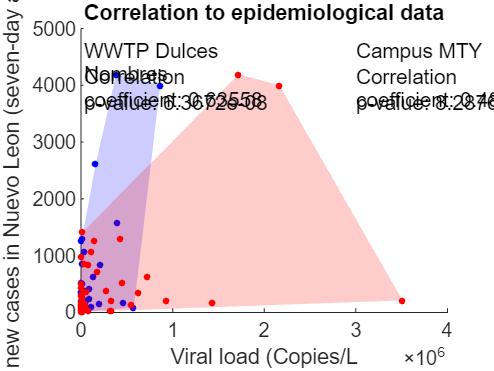

kWBEC=convhull(WBEC.Max_Copies,WBEC.CasesNL);
kWWTP=convhull(WWTP.WWTP_Copies_L,WWTP.CasesNL);
scatter(WWTP.WWTP_Copies_L,WWTP.CasesNL,10,'blue','filled','o')
hold on
fill(WWTP.WWTP_Copies_L(kWWTP),WWTP.CasesNL(kWWTP),'blue','FaceAlpha',0.2,'LineStyle','none')
annotation('textbox','String',Note1_WWTP,'FitBoxToText','on','Position',[0.15 0.85 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note2_WWTP,'FitBoxToText','on','Position',[0.15 0.78 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note3_WWTP,'FitBoxToText','on','Position',[0.15 0.71 0.445 0.06],'LineStyle','none');
scatter(WBEC.Max_Copies,WBEC.CasesNL,10,'red','filled','o')
fill(WBEC.Max_Copies(kWBEC),WBEC.CasesNL(kWBEC),'red','FaceAlpha',0.2,'LineStyle','none')
annotation('textbox','String',Note1_WBEC,'FitBoxToText','on','Position',[0.70 0.85 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note2_WBEC,'FitBoxToText','on','Position',[0.70 0.78 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note3_WBEC,'FitBoxToText','on','Position',[0.70 0.71 0.445 0.06],'LineStyle','none');
hold off
title('Correlation to epidemiological data');
ylabel('Daily new cases in Nuevo Leon (seven-day average)');
xlabel('Viral load (Copies/L');

## Correlation between both data sets and clinical incidence reports during 2022


WBEC_N=WBEC(WBEC.Week>51,:)

WBEC_N = 16x4 table
    Week    AVG_Copies    Max_Copies    CasesNL
    ____    __________    __________    _______

     55          91640    2.1643e+06    4002.3 
     56     1.2024e+05    1.7205e+06    4193.9 
     63          15960    3.1902e+05    39.714 
     64         9422.9    3.3192e+05    39.143 
     65         4052.6         80589        29 
     66         898.76         15279        22 
     67         122.35          1509        14 
     69              0             0    9.4286 
     70              0             0         9 
     71            156          4680    15.857 
     73         1869.6         14254    54.143 
     74          55226     5.519e+05    131.71 
     75     1.2682e+05    9.2853e+05       210 
     76          20689    6.2351e+05    345.43 
     77          62501    4.5072e+05    530.57 
     78         8535.9     

WWTP_N=WWTP(WWTP.Week>51,:)

WWTP_N = 20x3 table
    Week    WWTP_Copies_L    CasesNL
    ____    _____________    _______

     53           88779      420.14 
     54       3.993e+05      1576.4 
     55      8.6409e+05      4002.3 
     56      3.8319e+05      4193.9 
     57      1.6074e+05      2620.3 
     63               0      39.714 
     64               0      39.143 
     65               0          29 
     66               0          22 
     67               0          14 
     69               0      9.4286 
     70               0           9 
     71               0      15.857 
     72               0      35.143 
     73               0      54.143 
     74               0      131.71 



[cWBEC_N,pWBEC_N]=corrcoef(WBEC_N.Max_Copies,WBEC_N.CasesNL);
CorrWBEC_N=[cWBEC_N(2,1) pWBEC_N(2,1)]

CorrWBEC_N =     0.8939    0.0000


Note1_WBEC_N="Campus MTY";
Note2_WBEC_N=join(cat(2,"Correlation coefficient:",CorrWBEC_N(1,1)));
Note3_WBEC_N=join(cat(2,"p-value:",CorrWBEC_N(1,2)));
[cWWTP_N,pWWTP_N]=corrcoef(WWTP_N.WWTP_Copies_L,WWTP_N.CasesNL);
CorrWWTP_N=[cWWTP_N(2,1) pWWTP_N(2,1)]

CorrWWTP_N =     0.8655    0.0000


Note1_WWTP_N="WWTP Dulces Nombres";
Note2_WWTP_N=join(cat(2,"Correlation coefficient:",CorrWWTP_N(1,1)));
Note3_WWTP_N=join(cat(2,"p-value:",CorrWWTP_N(1,2)));

## Graphical comparison

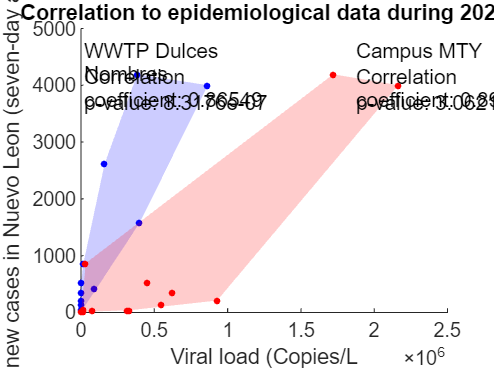

kWBEC_N=convhull(WBEC_N.Max_Copies,WBEC_N.CasesNL);
kWWTP_N=convhull(WWTP_N.WWTP_Copies_L,WWTP_N.CasesNL);
scatter(WWTP_N.WWTP_Copies_L,WWTP_N.CasesNL,10,'blue','filled','o')
hold on
fill(WWTP_N.WWTP_Copies_L(kWWTP_N),WWTP_N.CasesNL(kWWTP_N),'blue','FaceAlpha',0.2,'LineStyle','none')
annotation('textbox','String',Note1_WWTP_N,'FitBoxToText','on','Position',[0.15 0.85 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note2_WWTP_N,'FitBoxToText','on','Position',[0.15 0.78 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note3_WWTP_N,'FitBoxToText','on','Position',[0.15 0.71 0.445 0.06],'LineStyle','none');
scatter(WBEC_N.Max_Copies,WBEC_N.CasesNL,10,'red','filled','o')
fill(WBEC_N.Max_Copies(kWBEC_N),WBEC_N.CasesNL(kWBEC_N),'red','FaceAlpha',0.2,'LineStyle','none')
annotation('textbox','String',Note1_WBEC_N,'FitBoxToText','on','Position',[0.70 0.85 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note2_WBEC_N,'FitBoxToText','on','Position',[0.70 0.78 0.445 0.06],'LineStyle','none');
annotation('textbox','String',Note3_WBEC_N,'FitBoxToText','on','Position',[0.70 0.71 0.445 0.06],'LineStyle','none');
hold off
title('Correlation to epidemiological data during 2022');
ylabel('Daily new cases in Nuevo Leon (seven-day average)');
xlabel('Viral load (Copies/L');

## Urban mobility plot for the Monterrey Metropolitan Area during the study period

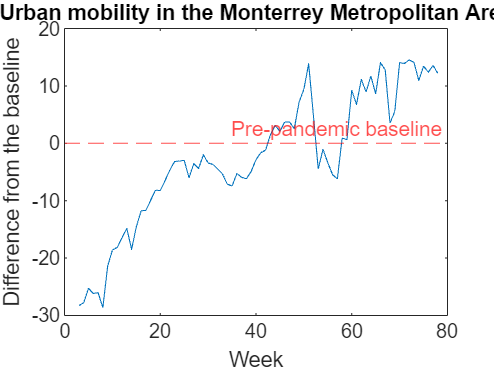

Mob=Datos_MTY(:,["Week","AVG_Mob"]);
plot(Mob.Week,Mob.AVG_Mob)
yline(0,"--r","Pre-pandemic baseline")
xlabel("Week")
ylabel("Difference from the baseline")
title("Urban mobility in the Monterrey Metropolitan Area")